# Jeff Suitor - 400138679 - 4QZ3 Final

clc
close all
clear all

data = [
    0.17;
    1.45;
    1.96;
    2.11;
    3.65;
    4.28;
    5.43;
    6.14;
    7.91;
    8.56;
    9.1;
    9.99;
    11.14;
    12.56;
    13.12;
    13.78;
    15;
    15.98
];

NN = zeros(17, 1);
for i = 2:length(data)
    NN(i-1) = (data(i) - data(i-1)) * 1000; % convert to ms
end

NN

NN = 	1.0e+03 *

    1.2800
    0.5100
    0.1500
    1.5400
    0.6300
    1.1500
    0.7100
    1.7700
    0.6500
    0.5400


AVNN = mean(NN)

AVNN = 930.0000

stdev = std(NN)

stdev = 432.2037


NN_copy = NN;
RD = zeros(17,1);

std(NN(1:2,1))/mean(NN(1:2,1))

ans = 0.6083


for i = 17:-1:1
    RD(i) = round(std(NN_copy)/mean(NN_copy),4);
    NN_copy(i) = [];
end

f = figure

f =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [680 558 560 420]
       Units: 'pixels'

  Show all properties


RD_10 = log10(RD(2:17))

RD_10 =    -0.2159
   -0.0493
   -0.1270
   -0.1571
   -0.2191
   -0.2431
   -0.2409
   -0.2450
   -0.2389
   -0.2616


m0_10 = log10(2:17)

m0_10 =     0.3010    0.4771    0.6021    0.6990    0.7782    0.8451    0.9031    0.9542    1.0000    1.0414    1.0792    1.1139    1.1461    1.1761    1.2041    1.2304


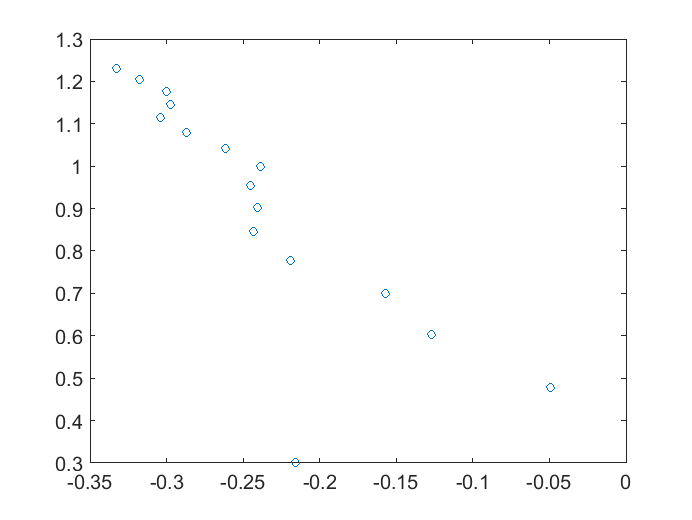

plot(RD_10, m0_10, 'o')

model = fitlm(RD_10, m0_10)

model = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    0.18441     0.13604     1.3555       0.19671
    x1             -3.0233     0.54266    -5.5714    6.8881e-05


Number of observations: 16, Error degrees of freedom: 14
Root Mean Squared Error: 0.159
R-squared: 0.689,  Adjusted R-Squared: 0.667
F-statistic vs. constant model: 31, p-value = 6.89e-05

plot(model)
model.Coefficients

ans = 2×4 table
                   Estimate      SE        tStat       pValue  
                   ________    _______    _______    __________

    (Intercept)    0.18441     0.13604     1.3555       0.19671
    x1             -3.0233     0.54266    -5.5714    6.8881e-05


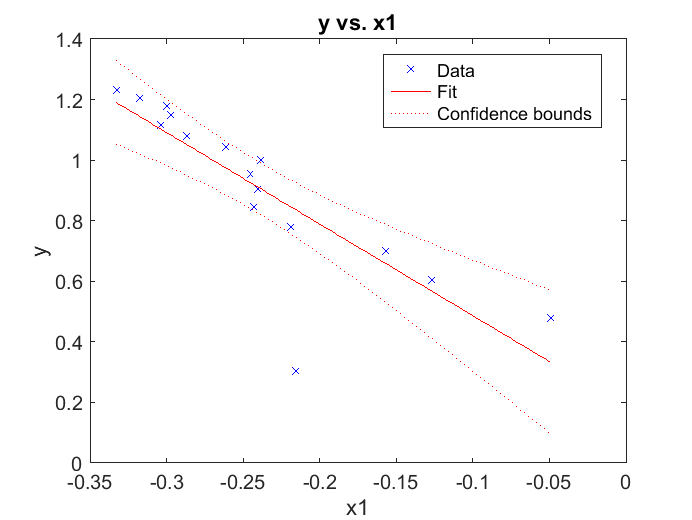

exportgraphics(f, "A_Q2.png")